times=1000;
snr=1:12;
snr=10*log10(snr)

snr =                    0   3.010299956639812   4.771212547196624   6.020599913279624   6.989700043360188   7.781512503836437   8.450980400142567   9.030899869919436   9.542425094393248  10.000000000000000  10.413926851582250  10.791812460476249


h1=semilogy(snr,LBFGS_1_2/1000,"LineWidth",1.6,"Marker","*","Color",'g');
xlabel('SNR(dB)')
ylabel("BER")
hold on;
grid ON
 h2=semilogy(snr,LBFGS_1_3/1000,"LineWidth",1.6,"Marker","*");
h3=semilogy(snr,LBFGS_B_2/1000,"LineWidth",1.6,"Marker","+","Color",'g');
 h4=semilogy(snr,LBFGS_B_3/1000,"LineWidth",1.6,"Marker","*");
 h5=semilogy(snr,LBFGS_D_2/1000,"LineWidth",1.6,"Marker","*","Color",'b');
 h6=semilogy(snr,LBFGS_D_3/1000,"LineWidth",1.6,"Marker","<","Color",'blue');
 h7=semilogy(snr,inv/1000,"LineWidth",1.6,"Marker","*")

h7 =   Line - 属性:

              Color: [0.635000000000000 0.078000000000000 0.184000000000000]
          LineStyle: '-'
          LineWidth: 1.600000000000000
             Marker: '*'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 3.010299956639812 4.771212547196624 6.020599913279624 6.989700043360188 7.781512503836437 8.450980400142567 9.030899869919436 9.542425094393248 10 10.413926851582250 10.791812460476249]
              YData: [0.091937500000000 0.029500000000000 0.010375000000000 0.003875000000000 0.001437500000000 5.000000000000000e-04 3.125000000000000e-04 6.250000000000000e-05 0 0 0 0]
              ZData: [1×0 double]

  显示 所有属性


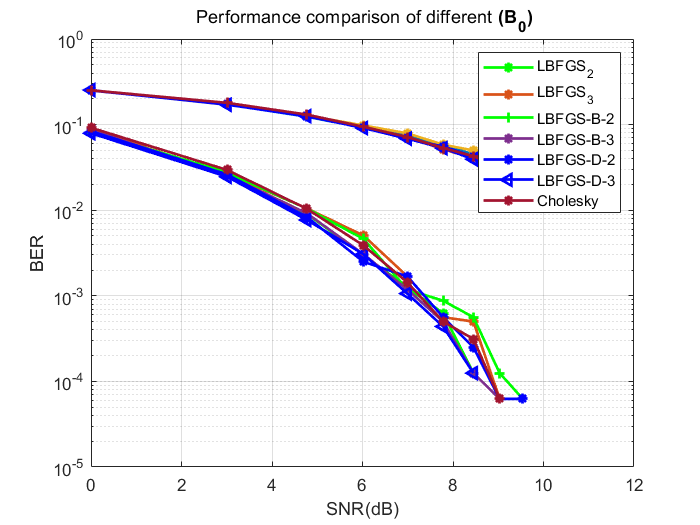


 
 semilogy(snr,LBFGS_1_2_16/1000,"LineWidth",1.6,"Marker","*")
 semilogy(snr,LBFGS_1_3_16/1000,"LineWidth",1.6,"Marker","*")
 semilogy(snr,LBFGS_B_2_16/1000,"LineWidth",1.6,"Marker","*")
 semilogy(snr,LBFGS_B_3_16/1000,"LineWidth",1.6,"Marker","*")
 semilogy(snr,LBFGS_D_2_16/1000,"LineWidth",1.6,"Marker","*","Color",'b')
 semilogy(snr,LBFGS_D_3_16/1000,"LineWidth",1.6,"Marker","<","Color",'blue')
 semilogy(snr,inv_16/1000,"LineWidth",1.6,"Marker","+")
 legend([h1,h2,h3,h4,h5,h6,h7],"LBFGS_2","LBFGS_3","LBFGS-B-2","LBFGS-B-3","LBFGS-D-2","LBFGS-D-3",'Cholesky')
 title(' Performance comparison of different \bf(B_0)')